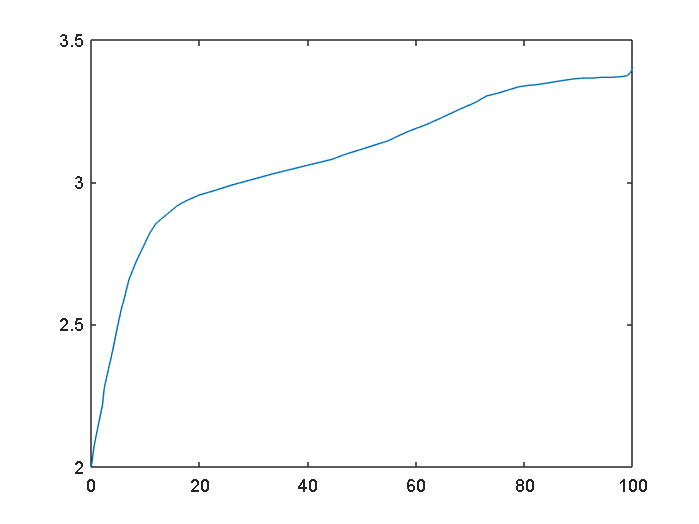

tableDchg = readtable("full_cell_cover2_discharge.csv");
cVecDchg = table2array(tableDchg(:,"capacity"));
vVecDchg = table2array(tableDchg(:,"voltage"));

SOC = 100 - cVecDchg / max(cVecDchg) * 100;
plot(SOC, vVecDchg)

sampleSOCVec = 10:10:100;
current = 1.14*10; % mA/cm^2, equivalent to 5C
powerRequirement = 27.36; % mW/cm^2

powerVec = [];

for sampleSOC = sampleSOCVec

    voltage = interp1(SOC, vVecDchg, sampleSOC);
    power = current*voltage;
    powerVec = [powerVec power];

end

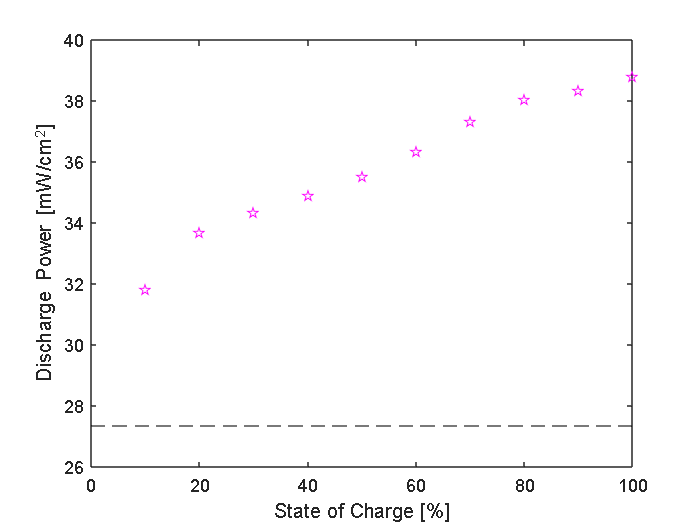

plot(sampleSOCVec, powerVec, 'p', color="magenta")
hold on
yline(powerRequirement, 'k--')
ylabel("Discharge Power [mW/cm^2]")
xlabel("State of Charge [%]")

%ylim([10,16])